# Step 4: 潮流計算

系統モデルの潮流計算を実行し、結果を表と図で確かめる方法をまとめます。計算の条件の確かめ方、`calculate_powerflow` のオプション、結果（`ResultPF`）の読み方、収束しないときの見分け方、`initialize` との関係を順に説明します。

この Step は、GUILDA の基本的な流れの赤枠の部分です。

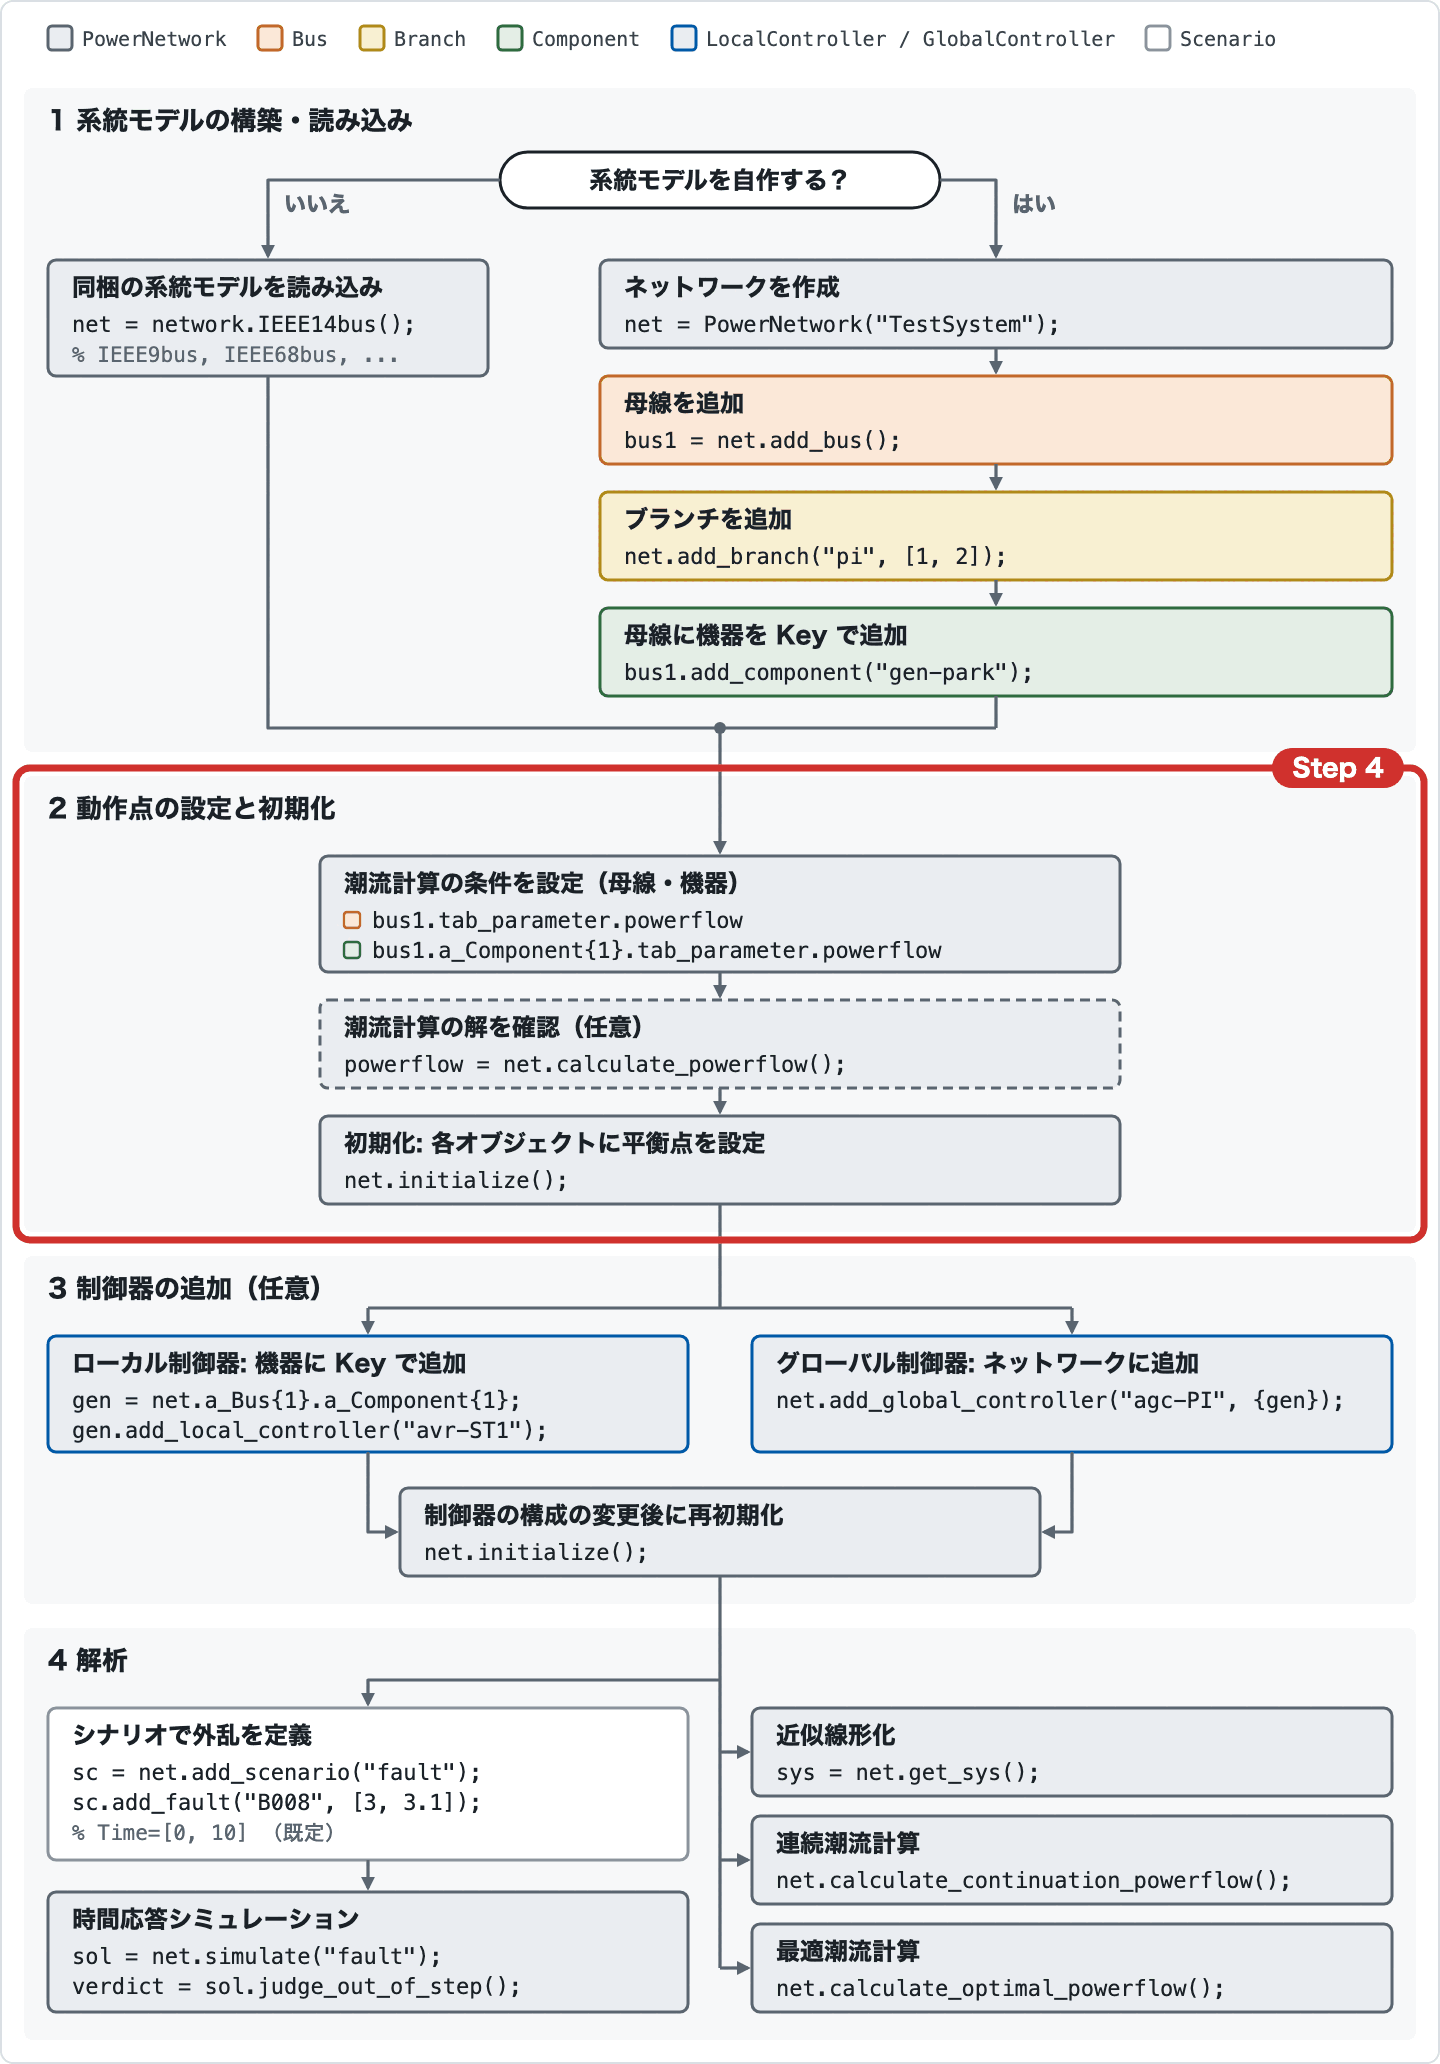

## この Step で分かること

- 潮流計算の条件（母線の種類と指定値）と、その値がどこから来るか

- `net.calculate_powerflow` の実行と、計算方法・初期値などのオプションの指定

- 結果 `ResultPF` を `disp_*` で表に、`plot_*` で図にする方法

- 運転上の上下限を外れた値の調べ方と、収束しなかったことの見分け方（`flag`）

- 潮流計算と `initialize`（平衡点の計算）の違い

各節のコードは、その節の作業に要るものだけです。中身を表示して確かめるコードは「**確かめる（省略できます）**」の下に分けてあります。飛ばしても、最後まで実行できます。

潮流計算の考え方は、Part 2 と知識ページ [Part 2: 潮流計算](matlab:web("https://guilda-dev.github.io/guilda-doc/lecture/part2-power-flow.html","-browser")) で説明しています。

**注意:** GUILDA を起動してから（`>> GUILDA`）実行してください。

## 1. 系統を読み込む

同梱の IEEE 9 母線系統を読み込みます。発電機 3 台と負荷 3 つの小さな系統です。系統の作り方は Step 1 で説明しています。

net = network.IEEE9bus();

## 2. 潮流計算の条件

潮流計算は、母線ごとの種類と指定値から、すべての母線の電圧を求めます。slack 母線は電圧の大きさ `V` と位相角 `Varg`、PV 母線は `P` と `V`、PQ 母線は `P` と `Q` を指定します。`P`・`Q` はネットワークへの注入で、負荷のある母線では負の値になります。

指定値は、モデルのパラメータから決まります。

- 母線の `P`・`Q` は、その母線にある機器の `tab_parameter.powerflow` の和です。発電機は `Q` が `NaN`（slack 母線の発電機は `P` も `NaN`）で、`Q` の和が `NaN` になる母線が PV 母線になります。

- PV 母線と slack 母線の電圧は、母線の `tab_parameter.powerflow` の `V`（slack 母線は `Varg` も）から取ります。

- slack 母線は、母線の `l_isSlack` が `true` の母線です。

この節では、計算のために書くコードはありません。条件は `get_pf_condition` で確かめられます。

**確かめる（省略できます）**

出力を受け取らずに呼ぶと、母線の表を表示します。`Type` が母線の種類、`NaN` の欄が計算で求める量です。

net.get_pf_condition();

Bus
             Type      Varg      V        P        Q  
            _______    ____    _____    _____    _____

    B001    "slack"      0      1.04      NaN      NaN
    B002    "PV"       NaN     1.025     1.63      NaN
    B003    "PV"       NaN     1.025     0.85      NaN
    B004    "PQ"       NaN       NaN        0        0
    B005    "PQ"       NaN       NaN    -1.25     -0.5
    B006    "PQ"       NaN       NaN     -0.9     -0.3
    B007    "PQ"       NaN       NaN        0        0
    B008    "PQ"       NaN       NaN       -1    -0.35
    B009    "PQ"       NaN       NaN        0        0



発電機と負荷の指定値と、母線の指定値を `get_parameter` でまとめて見ます。slack 母線が B001 であることも確かめます。

net.get_parameter("powerflow", Key="gen-1axis")

ans = 3×2 table
                P       Q 
               ____    ___

    B001SG1     NaN    NaN
    B002SG1    1.63    NaN
    B003SG1    0.85    NaN


net.get_parameter("powerflow", Class="component.load.abstract")

ans = 3×2 table
                  P        Q  
                _____    _____

    B005LRX1    -1.25     -0.5
    B006LRX1     -0.9     -0.3
    B008LRX1       -1    -0.35


net.get_parameter("powerflow", Class="Bus")

ans = 9×2 table
              V      Varg
            _____    ____

    B001     1.04     0  
    B002    1.025     0  
    B003    1.025     0  
    B004        1     0  
    B005        1     0  
    B006        1     0  
    B007        1     0  
    B008        1     0  
    B009        1     0  


net.get_element("B001").l_isSlack

ans = logical
   1


**注意:** slack 母線は利用者が選びます（`net.get_element("B001").l_isSlack = true`）。GUILDA が自動で選ぶことはなく、slack 母線がないと `GUILDA:PowerNetwork:NoSlackBus` のエラーになります。指定値の書き換え方は Step 3 で説明しています。

## 3. 潮流計算を実行する

`calculate_powerflow` は 3 つの値を返します。1 番目が結果（`ResultPF`）、2 番目が収束の判定 `flag`、3 番目が計算の記録 `output` です。

[result, flag, output] = net.calculate_powerflow();
flag

flag = 1

`flag` が 1 なら収束しています。結果の概要は `disp_summary` で表示します。

result.disp_summary();

Power flow of PowerNetwork (Solver newton): converged, flag 1
- Calculation: 0 iterations, largest residual 6.16e-15 pu, elapsed 0.0105 s
- Message: ✔ The Newton-Raphson iteration has converged within the tolerance limit (0 iterations).
- Network: 9 buses (slack 1, PV 2, PQ 6), 9 branches
- Generation: P = 3.1964 pu, Q = 0.2284 pu
- Load: P = 3.1500 pu, Q = 1.1500 pu
- Losses: P = 0.0464 pu, Q = -0.9216 pu
- |V|: max 1.0400 pu at B001, min 0.9956 pu at B005
- Violated operating limits: 0


1 行目が計算方法と収束の判定、続いて反復回数、母線とブランチの数、発電・負荷・損失の合計、電圧の大きさの最大と最小、運転上の上下限を外れた数です。

**確かめる（省略できます）**

`output` には反復回数、計算方法、不平衡量の最大値（`residual`）、メッセージが入ります。反復回数が 0 なのは、`network.IEEE9bus()` が読み込むときに一度潮流計算を解いていて、その解から始めた（`WarmStart`、4 節）ためです。`disp_summary` と同じ値は、`get_summary` で構造体として受け取れます。

output

output = フィールドをもつ struct:
    iterations: 0
     algorithm: "newton"
      residual: 6.1617e-15
       message: '✔ The Newton-Raphson iteration has converged within the tolerance limit (0 iterations).'


sct_summary = result.get_summary();
[sct_summary.r_Ploss, sct_summary.r_Vmin]

ans =     0.0464    0.9956


sct_summary.s_VminBus

ans = "B005"

**注意:** 潮流計算はモデル `net` を書き換えません。結果はすべて `result` に入り、`result` はモデルを参照しないので、後で `net` を書き換えても変わりません。

## 4. 計算のオプションを指定する

Name=Value のオプションで、その呼び出しだけ計算の方法を変えられます。ここでは 3 つを使います。

- `Solver`: 計算方法。既定はニュートン法 `"newton"` です。

- `WarmStart`: 前回収束した解から始めるか。`false` にすると、フラットスタート（位相角 0、電圧の大きさ 1 pu）から解きます。

- `Progress`: 進み具合の表示。`"none"` で表示しません。既定の `"dialog"` は、計算が 0.5 秒以上かかったときだけ小さな画面を開きます。

レーベンバーグ・マーカート法で、フラットスタートから解きます。

resultLM = net.calculate_powerflow(Solver="levenberg-marquardt", WarmStart=false, Progress="none");
resultLM.disp_summary();

Power flow of PowerNetwork (Solver levenberg-marquardt): converged, flag 1
- Calculation: 4 iterations, largest residual 3.43e-13 pu, elapsed 0.0873 s
- Message: ✔ The Levenberg-Marquardt iteration has converged within the tolerance limit (4 iterations).
- Network: 9 buses (slack 1, PV 2, PQ 6), 9 branches
- Generation: P = 3.1964 pu, Q = 0.2284 pu
- Load: P = 3.1500 pu, Q = 1.1500 pu
- Losses: P = 0.0464 pu, Q = -0.9216 pu
- |V|: max 1.0400 pu at B001, min 0.9956 pu at B005
- Violated operating limits: 0


許容値 `Tolerance`、反復回数の上限 `MaxIteration`、反復ごとの表示 `Verbose`・`PlotFcn` など、[その他のオプションはこちら](matlab:writelines("<script>location.replace('file://"+replace(fullfile(GUILDA.pwd,"_GUILDAdoc","method.html"),filesep,"/")+"#class=PowerNetwork&method=calculate_powerflow')</script>",fullfile(tempdir,"guilda_doc.html"));web(fullfile(tempdir,"guilda_doc.html"),"-browser"))（ブラウザで開きます）。

**確かめる（省略できます）**

今の既定値は `GUILDA.config` で表として見られます。

GUILDA.config("PowerFlowCalculation", Format="table")

ans = 12×4 table
                 Name                   Type           Value                                                                                            Description                                                                                    
    ______________________________    _________    ______________    __________________________________________________________________________________________________________________________________________________________________________________

    "Solver"                          "select"     {["newton"  ]}    "Algorithm: 'newton', 'gradient', 'levenberg-marquardt', 'fsolve' (needs Optimization Toolbox) or 'dynamic' (virtual bus dynamics)"                                               
    "Tolerance"                       "double"     {[1.0000e-08]}    "[pu] Largest P/Q mismatch of a converged solution (every method)"                                                                                                       

計算方法ごとに、フラットスタートから解き、反復回数と不平衡量を比べます。

sv_solver = ["newton", "levenberg-marquardt", "fsolve", "gradient", "dynamic"];
for k = 1:numel(sv_solver)
    resultSolver = net.calculate_powerflow(Solver=sv_solver(k), WarmStart=false, Progress="none");
    sct_solver(k) = resultSolver.get_summary();
end
tab_solver = struct2table(sct_solver);
tab_solver(:, ["s_Solver", "r_flag", "n_iteration", "r_residual"])

ans = 5×4 table
          s_Solver           r_flag    n_iteration    r_residual
    _____________________    ______    ___________    __________

    "newton"                   1             4        6.1617e-15
    "levenberg-marquardt"      1             4         3.434e-13
    "fsolve"                   1             5        3.3455e-15
    "gradient"                 1          1351         9.988e-09
    "dynamic"                  1           277             1e-08


`r_flag` が収束の判定、`n_iteration` が反復回数、`r_residual` が不平衡量の最大値です。どの方法でも同じ解に収束します。ニュートン法は数回、勾配法（`gradient`）は千回以上の反復が要ります。`dynamic` は母線に仮想的なダイナミクスを持たせて時間積分する方法で、反復回数の代わりに積分のステップの数を数えます。`"fsolve"` は Optimization Toolbox が要ります。

`Verbose=true` で反復ごとの経過を、`PlotFcn="residual"` で反復ごとの不平衡量（式 1 本につき 1 本の棒、対数軸。破線が `Tolerance`）を表示します。

  newton  iter    0   max mismatch 1.630e+00
  newton  iter    1   max mismatch 1.054e-01
  newton  iter    2   max mismatch 1.303e-03
  newton  iter    3   max mismatch 2.042e-07
  newton  iter    4   max mismatch 6.162e-15
✔ The Newton-Raphson iteration has converged within the tolerance limit (4 iterations).


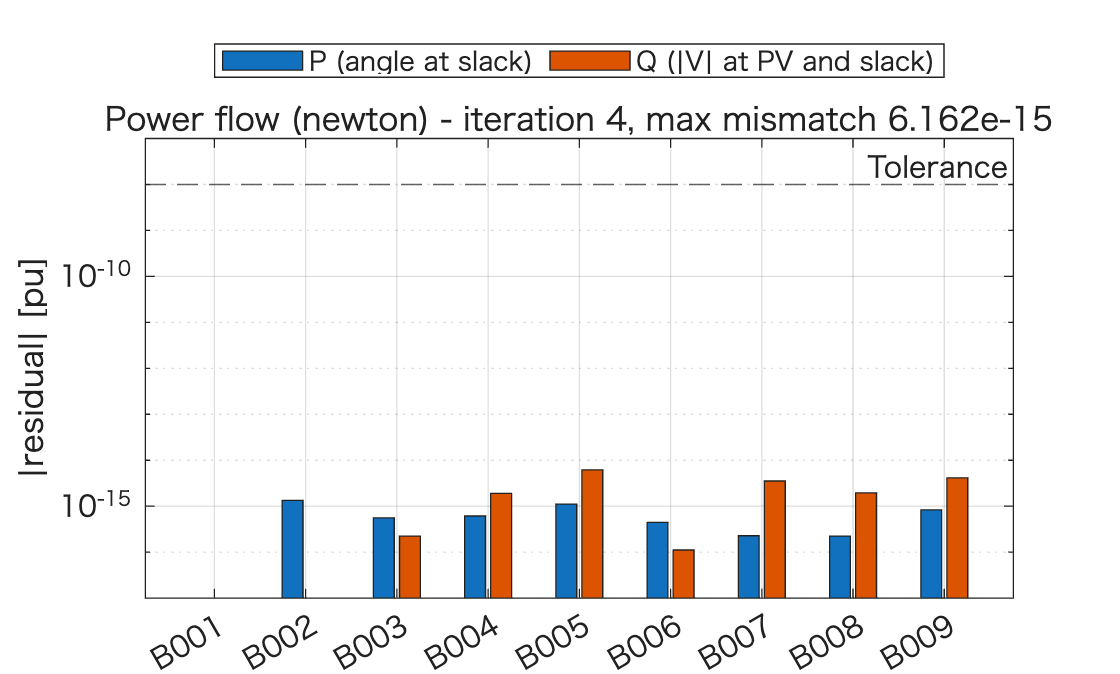

[~, flag] = net.calculate_powerflow(WarmStart=false, Verbose=true, PlotFcn="residual", Progress="none");

**注意:** 既定値そのものは `GUILDA.setting("PowerFlowCalculation", Solver="levenberg-marquardt")` のように変えます（Step 11）。収束しなかったときの扱い `WhenFailed` など、Name=Value では指定できない設定も `GUILDA.setting` で変えます。

## 5. 結果の形を選ぶ（Format）

`ResultPF` が要らないときは、`Format` で 1 番目の出力の形を選べます。`"V"` は母線の複素電圧の列ベクトル（`net.a_Bus` の順）、`"powerflow(tab)"` は母線ごとの電圧 `V`、電流 `I`（ネットワークへの注入、複素数）、`P`、`Q` の表です。`"powerflow(mat)"` は同じ内容の 4 列の複素行列です。

V = net.calculate_powerflow(Format="V");
tab_powerflow = net.calculate_powerflow(Format="powerflow(tab)");

**確かめる（省略できます）**

V

V =    1.0400 + 0.0000i
   1.0116 + 0.1653i
   1.0216 + 0.0834i
   1.0250 - 0.0397i
   0.9932 - 0.0693i
   1.0106 - 0.0651i
   1.0236 + 0.0665i
   1.0158 + 0.0129i
   1.0317 + 0.0354i


tab_powerflow

tab_powerflow = 9×4 table
                    V                       I                    P             Q     
            _________________    _______________________    ___________    __________

    B001       1.04+0i               0.68886-0.26006i           0.71641       0.27046
    B002     1.0116+0.16529i          1.5799+0.19238i              1.63      0.066537
    B003     1.0216+0.083358i        0.81791+0.17304i              0.85       -0.1086
    B004      1.025-0.039678i    -9.2981e-16+3.5111e-15i    -1.0924e-15    -3.562e-15
    B005    0.99322-0.069258i        -1.2175+0.58831i             -1.25          -0.5
    B006     1.0106-0.065127i       -0.86786+0.3528i               -0.9          -0.3
    B007     1.0236+0.066547i     3.1225e-16-5.6344e-15i    -5.5331e-17    5.7882e-15
    B008     1.0158+0.012899i       -0.98866+0.332i                  -1         -0.35
    B009     1.0317+0.035429i     1.4572e-16-9.7145e-16i     1.1592e-16    1.0074e-15


**注意:** `Format` が `"GUILDAorigin"`（既定）以外のときは、`ResultPF` を作らないぶん速く計算できます。2 番目と 3 番目の出力（`flag`、`output`）は同じです。

## 6. 結果を表で読む

`disp_bus` は母線ごとの指定値と計算結果（電圧、注入電力）を、`disp_branch` はブランチごとの潮流と損失を表示します。`Unit="SI"` で kV・MW・Mvar にし、`Sort` で並べ替えます。`Sort="V"` は電圧の低い順、`Sort="loss"` は損失の大きい順です。

result.disp_bus(Unit="SI", Sort="V");

             Type          Set (pu)         |V| (kV)    Varg (deg)      P (MW)        Q (Mvar) 
            _______    _________________    ________    __________    ___________    __________

    B005    "PQ"       "P=-1.25, Q=-0.5"        229      -3.9888             -125           -50
    B006    "PQ"       "P=-0.9, Q=-0.3"      232.91      -3.6874              -90           -30
    B008    "PQ"       "P=-1, Q=-0.35"       233.65      0.72754             -100           -35
    B002    "PV"       "P=1.63, V=1.025"     235.75         9.28              163        6.6537
    B003    "PV"       "P=0.85, V=1.025"     235.75       4.6648               85        -10.86
    B007    "PQ"       "P=0, Q=0"            235.93       3.7197      -5.5331e-15    5.7882e-13
    B004    "PQ"       "P=0, Q=0"            235.93      -2.2168      -1.0924e-13    -3.562e-13
    B009    "PQ"       "P=0, Q=0"            237.44       1.9667       1.1592e-14    1.0074e-13
    B001    "slack"    "V=1.04, Varg=0"

result.disp_branch(Sort="loss");

              From       To      Pfrom (pu)    Qfrom (pu)    Pto (pu)    Qto (pu)     Ploss (pu)    Qloss (pu)    Loading
             ______    ______    __________    __________    ________    _________    __________    __________    _______

    EL006    "B005"    "B007"      -0.8432       -0.11313      0.8662    -0.083808         0.023     -0.19694       NaN  
    EL007    "B006"    "B009"     -0.59463       -0.13457     0.60817     -0.18075      0.013538     -0.31531       NaN  
    EL008    "B007"    "B008"       0.7638     -0.0079733    -0.75905     -0.10704     0.0047528     -0.11502       NaN  
    EL004    "B004"    "B005"      0.40937        0.22893     -0.4068     -0.38687     0.0025751     -0.15794       NaN  
    EL005    "B004"    "B006"      0.30704         0.0103    -0.30537     -0.16543     0.0016641     -0.15513       NaN  
    EL009    "B008"    "B009"     -0.24095       -0.24296     0.24183     0.031195    0.00087997     -0.21176       NaN  
    ET003    "B003"    

`disp_branch` の `Loading` はブランチの容量（`Smax`）に対する割合で、容量を決めていないブランチは `NaN` です。一部だけ表示するときは `result.disp_bus(Bus=["B005","B006"])` のように指定します。表示のオプションは [disp_bus](matlab:writelines("<script>location.replace('file://"+replace(fullfile(GUILDA.pwd,"_GUILDAdoc","method.html"),filesep,"/")+"#class=ResultPF&method=disp_bus')</script>",fullfile(tempdir,"guilda_doc.html"));web(fullfile(tempdir,"guilda_doc.html"),"-browser"))・[disp_branch](matlab:writelines("<script>location.replace('file://"+replace(fullfile(GUILDA.pwd,"_GUILDAdoc","method.html"),filesep,"/")+"#class=ResultPF&method=disp_branch')</script>",fullfile(tempdir,"guilda_doc.html"));web(fullfile(tempdir,"guilda_doc.html"),"-browser")) のリファレンスにあります（ブラウザで開きます）。

**確かめる（省略できます）**

表示のもとになる表は、`ResultPF` のプロパティです。`tab_bus` は母線ごとの電圧（位相角 `Varg` [rad]、大きさ `V` [pu]）、注入電力 `P`・`Q`、電圧と電流のフェーザです。

result.tab_bus

ans = 9×6 table
              Varg          V            P             Q              Vphasor                 Iphasor        
            _________    _______    ___________    __________    _________________    _______________________

    B001            0       1.04        0.71641       0.27046       1.04+0i               0.68886-0.26006i   
    B002      0.16197      1.025           1.63      0.066537     1.0116+0.16529i          1.5799+0.19238i   
    B003     0.081415      1.025           0.85       -0.1086     1.0216+0.083358i        0.81791+0.17304i   
    B004     -0.03869     1.0258    -1.0924e-15    -3.562e-15      1.025-0.039678i    -9.2981e-16+3.5111e-15i
    B005    -0.069618    0.99563          -1.25          -0.5    0.99322-0.069258i        -1.2175+0.58831i   
    B006    -0.064357     1.0127           -0.9          -0.3     1.0106-0.065127i       -0.86786+0.3528i    
    B007     0.064921     1.0258    -5.5331e-17    5.7882e-15     1.0236+0.066547i     3.1225e-16-5.634

`tab_branch` はブランチごとの潮流です。`Pfrom`・`Qfrom` は From 側の母線からブランチに流れ込む電力、`Pto`・`Qto` は To 側から流れ込む電力、`Ploss`・`Qloss` はブランチの損失です。

result.tab_branch(:, ["Pfrom", "Qfrom", "Pto", "Qto", "Ploss", "Qloss"])

ans = 9×6 table
              Pfrom        Qfrom         Pto          Qto         Ploss        Qloss  
             ________    __________    ________    _________    __________    ________

    ET001     0.71641       0.27046    -0.71641     -0.23923             0    0.031228
    ET002        1.63      0.066537       -1.63     0.091781             0     0.15832
    ET003        0.85       -0.1086       -0.85      0.14955    1.1102e-16    0.040956
    EL004     0.40937       0.22893     -0.4068     -0.38687     0.0025751    -0.15794
    EL005     0.30704        0.0103    -0.30537     -0.16543     0.0016641    -0.15513
    EL006     -0.8432      -0.11313      0.8662    -0.083808         0.023    -0.19694
    EL007    -0.59463      -0.13457     0.60817     -0.18075      0.013538    -0.31531
    EL008      0.7638    -0.0079733    -0.75905     -0.10704     0.0047528    -0.11502
    EL009    -0.24095      -0.24296     0.24183     0.031195    0.00087997    -0.21176


**注意:** 計算に使った条件とアドミタンス行列は `result.tab_PFcondition` と `result.cm_Y`、計算の設定は `result.options` に残ります。

## 7. 結果を図で見る

`plot_voltage` は母線の電圧の大きさと位相角の棒グラフです。既定では、電圧の運転上の上下限（`Vmin`、`Vmax`）も破線で描きます。

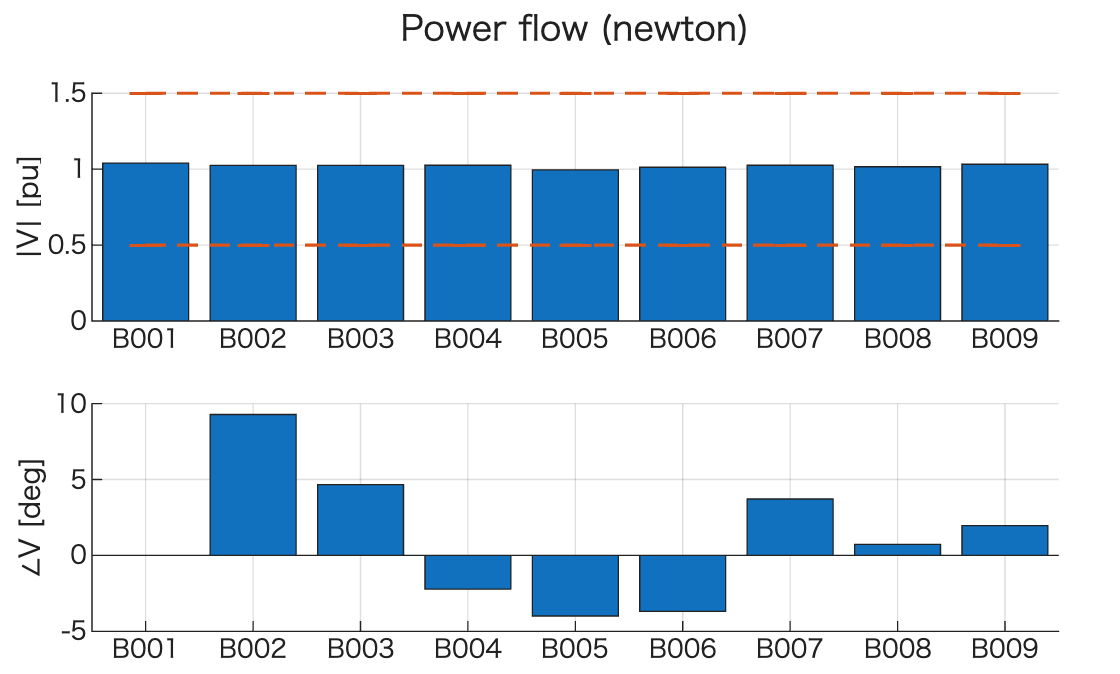

result.plot_voltage();

`plot_branch` はブランチごとの値の棒グラフです。`Quantity` に `"P"`、`"Q"`、`"S"`、`"loss"`、`"loading"` を指定します。

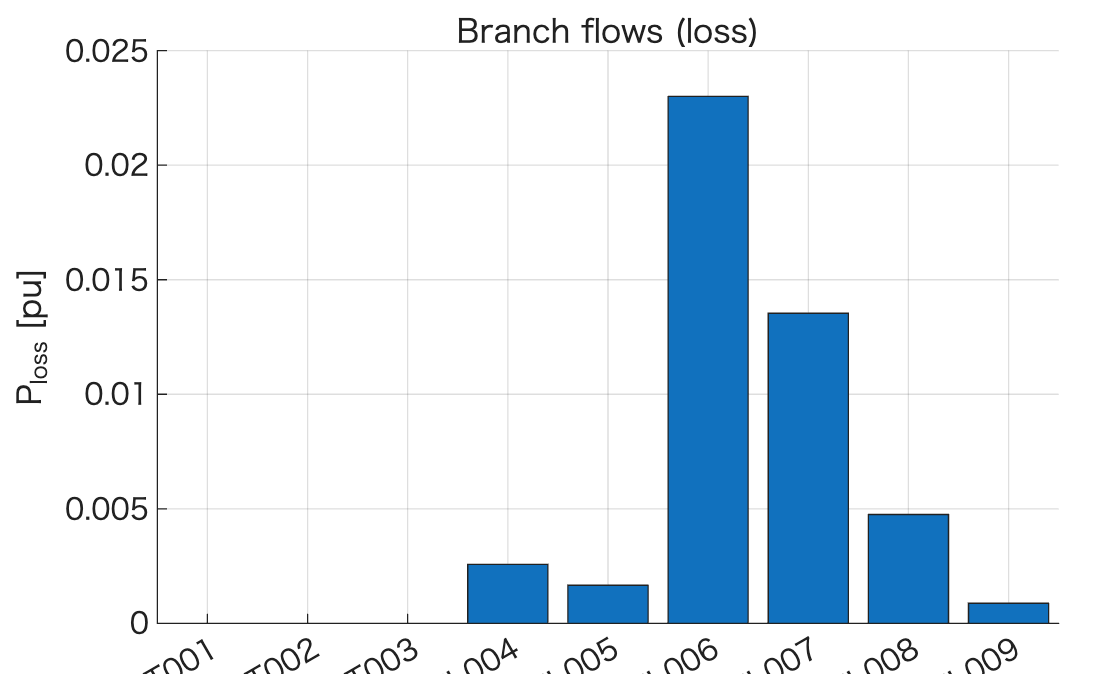

result.plot_branch(Quantity="loss");

`plot_network` は系統図の上に母線の電圧（点の色）と潮流の向き（矢印）を描きます。`Color` は `"V"` か `"angle"`、`Arrow` は `"P"`、`"Q"`、`"none"` です。

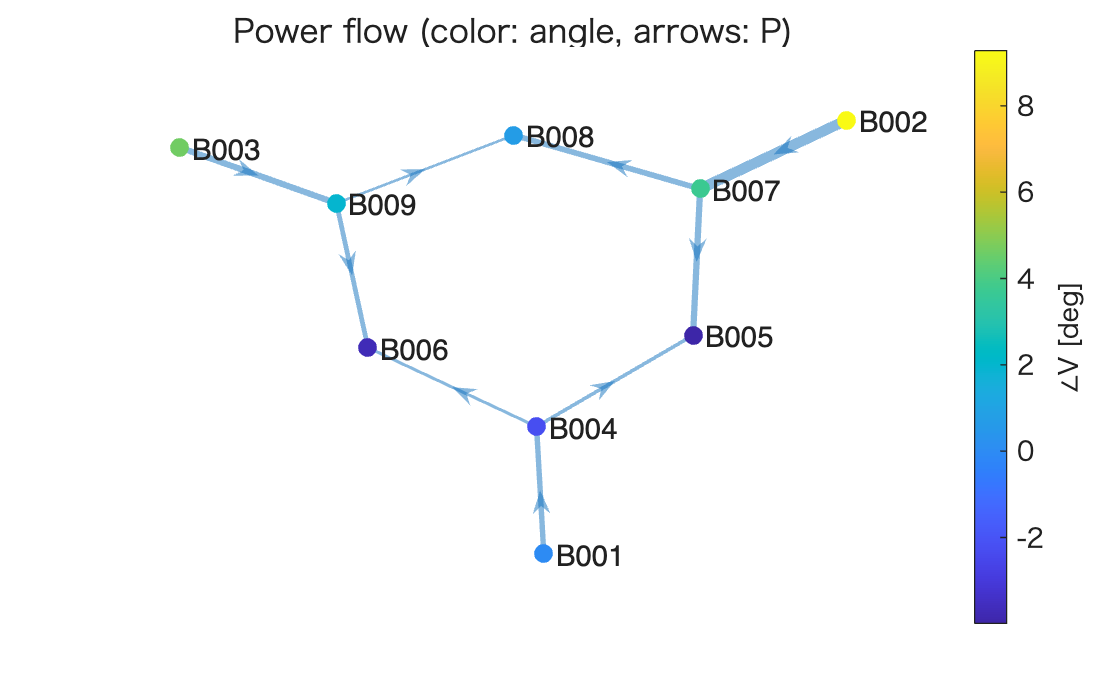

result.plot_network(Color="angle", Arrow="P");

`plot_convergence` は反復ごとの不平衡量の最大値です。反復が 0 回の `result` ではなく、4 節でフラットスタートから解いた `resultLM` で描きます。`Bus` を指定すると、その母線の電圧の大きさの変化も描きます。

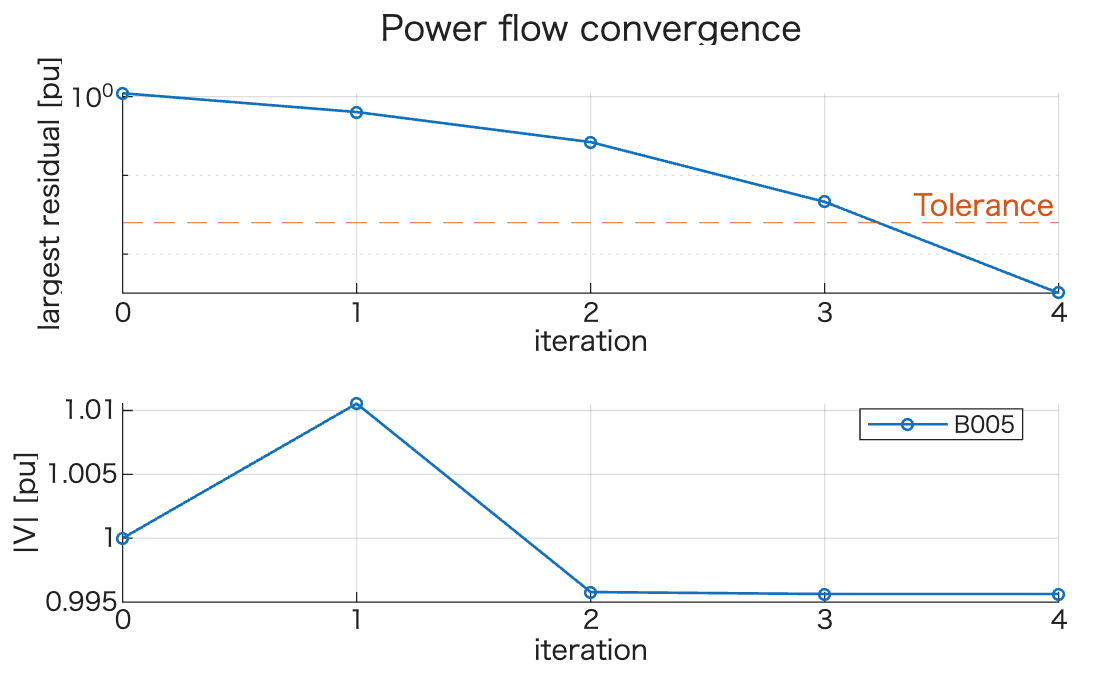

resultLM.plot_convergence(Bus="B005");

**注意**

- `plot_*` は描いた図のオブジェクト（`GraphBase` の子クラス）を返します。`Parent` に figure や axes を渡すと、その中に描きます（Step 7）。

- 系統図の `plot_diagram` と、ばね質点の絵 `plot_spring_model` は Step 7 と Part 4 で扱います。

- 表をファイルに書き出すには `result.export("pf.csv", Table="branch")` とします（Step 12）。

## 8. 運転上の上下限を外れた値を調べる

潮流計算そのものは上下限を使いませんが、結果の `tab_violation` に、解が運転上の上下限（`tab_parameter.operation`）を外れた箇所が入ります。ここでは試しに、母線 5 の電圧の下限 `Vmin` を 1.0 pu に上げて解き直し、`disp_violation` で外れた値を表示します。

tab_operation = net.get_parameter("operation", Class="Bus");
tab_operation{"B005", "Vmin"} = 1.0;
net.set_parameter("operation", tab_operation("B005", "Vmin"));
resultLimit = net.calculate_powerflow(Progress="none");
resultLimit.disp_violation();

Bus (1)
    Object    Limit      Value     Bound     Excess  
    ______    ______    _______    _____    _________

    "B005"    "Vmin"    0.99563      1      0.0043691



母線 5 の電圧 0.996 pu が下限 1.0 pu を下回っている、と分かります。`Excess` が外れた量です。上下限には、母線の `Vmin`・`Vmax`、機器の `Pmin`・`Pmax`・`Qmin`・`Qmax`、ブランチの `Smax`・`Imax` などがあります。下限を元に戻します。

tab_operation{"B005", "Vmin"} = 0.5;
net.set_parameter("operation", tab_operation("B005", "Vmin"));

**確かめる（省略できます）**

表示のもとになる表です。

resultLimit.tab_violation

ans = 1×6 table
    Class    Object    Limit      Value     Bound     Excess  
    _____    ______    ______    _______    _____    _________

    "Bus"    "B005"    "Vmin"    0.99563      1      0.0043691


**注意:** 外れた値があっても、警告やエラーにはなりません。`disp_summary` の最後の行にも、外れた数が出ます。

## 9. 収束しないときの見分け方

解けたかどうかは `flag` で見分けます。1 は収束、0 は反復回数の上限に達した、-1 は `PlotFcn` で止めた、-2 は解が見つからなかった、です。反復回数の上限を 2 にして、収束しない例を作ります。

[resultStop, flag] = net.calculate_powerflow(MaxIteration=2, WarmStart=false, Progress="none");

flag

flag = 0

収束しないと警告が出ます。結果の `l_success` は収束したときだけ `true` です。

次は、負荷を大きくしすぎて電力方程式の解がなくなる例です。別の系統を読み込み、3 つの負荷の有効電力と無効電力を 2.5 倍にします。

netHeavy = network.IEEE9bus();
tab_load = netHeavy.get_parameter("powerflow", Class="component.load.abstract");
tab_load{:, ["P", "Q"]} = 2.5 * tab_load{:, ["P", "Q"]};
netHeavy.set_parameter("powerflow", tab_load);
[resultHeavy, flag, output] = netHeavy.calculate_powerflow(Progress="none");

flag

flag = -2

今度は `flag` が -2 です。反復回数の上限を増やしても解けません。収束しなかった結果の `tab_bus` などの値は使えません。

**確かめる（省略できます）**

収束しなかった理由は `output.message` に、収束したかどうかは `l_success` と `disp_summary` の 1 行目（`not converged`）にも出ます。

output.message

ans = '✘ The process was terminated: the Newton-Raphson iteration diverged (largest mismatch 7.982e+12). The calculation from the kept solution (WarmStart) did not converge, so it was solved again from the flat start.'

[resultStop.l_success, resultHeavy.l_success]

ans = 1×2 の logical 配列
   0   0


resultStop.disp_summary();

Power flow of PowerNetwork (Solver newton): not converged, flag 0
- Calculation: 2 iterations, largest residual 0.0013 pu, elapsed 0.0432 s
- Message: ✘ The Newton-Raphson iteration did not converge within MaxIterations (2).
- Network: 9 buses (slack 1, PV 2, PQ 6), 9 branches
- Not converged: injection sums, |V| and violated limits are not shown


**注意**

- 収束しないときの扱いは設定 `WhenFailed` で選べます（Step 11）。既定は警告です。

- 解が見つからないときは、負荷や発電の指定値、slack 母線、ブランチのパラメータを確かめます。初期値を変えるには `WarmStart=false`、計算方法を変えるには `Solver="levenberg-marquardt"` などを試します。どこまで負荷を増やせるかは、連続潮流計算（Step 10）で調べられます。

## 10. initialize との関係

### 10.1 平衡点を求める

`calculate_powerflow` はモデルを書き換えずに解を返すだけです。時間シミュレーションや近似線形化に使う平衡点は、`initialize` で求めます。`initialize` は潮流計算を解き、その解を各母線に書き込み、機器と制御器の平衡点を計算します。

[rm_PF, flag] = net.initialize();
flag

flag = 1

`initialize` の 1 番目の出力は、書き込んだ動作点（母線ごとに電圧 `V`、電流 `I`、`P`、`Q` の 4 列の複素行列）で、2 番目が成否です。

**確かめる（省略できます）**

動作点と、母線 5 に書き込まれた電圧（`c_Vequilibrium`）を表示します。

rm_PF

rm_PF =    1.0400 + 0.0000i   0.6889 - 0.2601i   0.7164 + 0.0000i   0.2705 + 0.0000i
   1.0116 + 0.1653i   1.5799 + 0.1924i   1.6300 + 0.0000i   0.0665 + 0.0000i
   1.0216 + 0.0834i   0.8179 + 0.1730i   0.8500 + 0.0000i  -0.1086 + 0.0000i
   1.0250 - 0.0397i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.9932 - 0.0693i  -1.2175 + 0.5883i  -1.2500 + 0.0000i  -0.5000 + 0.0000i
   1.0106 - 0.0651i  -0.8679 + 0.3528i  -0.9000 + 0.0000i  -0.3000 + 0.0000i
   1.0236 + 0.0665i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   1.0158 + 0.0129i  -0.9887 + 0.3320i  -1.0000 + 0.0000i  -0.3500 + 0.0000i
   1.0317 + 0.0354i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i


net.get_element("B005").c_Vequilibrium

ans = 0.9932 - 0.0693i

### 10.2 モデルを書き換える

モデルを書き換えると、潮流計算と平衡点が古くなります。負荷の指定値を書き換えます。

tab_load = net.get_parameter("powerflow", Class="component.load.abstract");
tab_load{"B005LRX1", "P"} = -1.3;
net.set_parameter("powerflow", tab_load("B005LRX1", "P"));

**確かめる（省略できます）**

どの層を計算し直す必要があるかは、`sct_stale` に記録されます。負荷の指定値を書き換えたので、潮流計算が古くなっています。

net.sct_stale 

ans = フィールドをもつ struct:
    powerflow: "powerflow/B005LRX1: edit P: -1.25 -> -1.3"
       odefcn: [0×1 string]
        input: [0×1 string]


### 10.3 平衡点を求め直す

もう一度 `initialize` すると、潮流計算と平衡点が計算し直されます。

[~, flag] = net.initialize();
flag 

flag = 1

**確かめる（省略できます）**

計算し直したので、記録は空になります。

net.sct_stale 

ans = フィールドをもつ struct:
    powerflow: [0×1 string]
       odefcn: [0×1 string]
        input: [0×1 string]


**注意**

- `initialize` は、潮流計算が古くないときは潮流計算を解き直しません。`Method="powerflow"` を指定すると、いつでも解き直します。`Method="OPF"` で最適潮流計算（Step 9）の解を平衡点にすることもできます。

- 時間シミュレーション（`simulate`）や近似線形化（`get_sys`）は、平衡点が古いとエラーになります。モデルを書き換えたら `initialize` してから使います。

- `initialize` の [その他のオプションはこちら](matlab:writelines("<script>location.replace('file://"+replace(fullfile(GUILDA.pwd,"_GUILDAdoc","method.html"),filesep,"/")+"#class=PowerNetwork&method=initialize')</script>",fullfile(tempdir,"guilda_doc.html"));web(fullfile(tempdir,"guilda_doc.html"),"-browser"))（ブラウザで開きます）。

## まとめ

- 潮流計算の条件は、母線の種類と、機器と母線の `tab_parameter.powerflow` から決まります。`net.get_pf_condition()` で確かめられます。

- `net.calculate_powerflow()` で潮流計算を実行しました。オプションで計算方法や初期値などを変えられます。

- 結果 `ResultPF` を、`disp_*` で表に、`plot_*` で図にしました。上下限を外れた値は `disp_violation` で見ます。

- 収束したかどうかは `flag`（1 なら収束）で見分けます。

- 平衡点をモデルに書き込むのは `initialize` です。

## 次の Step と関係する Part

- 次の Step 5（時間シミュレーションの条件）では、シナリオを作って事故などの外乱を加える方法を説明します。

- 潮流計算の考え方と、負荷を増やしたときの電圧と損失の変化は Part 2（潮流計算）で扱います（`Part2_PowerFlow.mlx`）。

[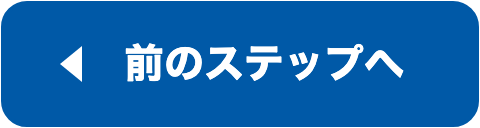](matlab:open('Step3_NetworkData.mlx'))　　[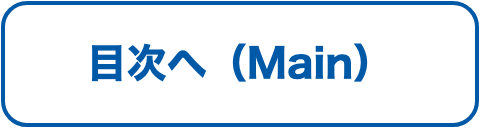](matlab:open('Main.mlx'))　　[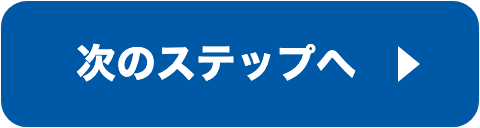](matlab:open('Step5_SimulationScenario.mlx'))